## F1 TRAJECTORY OPTIMIZATION

% 1. Geometric Optimization (V1)

% 2. Physics Comparison (Baseline vs Aero+Ellipse)

% 3. Iterative Optimization (V2 - Dynamic Path)

clear; clc; close all;


### 1. SETUP & DATA LOADING

fprintf('=== 1. SETUP & TRACK DATA ===\n');


=== 5. GENERATING PLOTS ===


# 1.1 Load Data

try
    track_data = readmatrix('Circuits_Data/Nuerburgring_track.csv');
catch
    error('Track file not found. Please check the file path.');
end

x_center = track_data(:,1);
y_center = track_data(:,2);
w_right  = track_data(:,3);
w_left   = track_data(:,4);
N = length(x_center);
%--- CRITICAL FIX: DATA CLEANING ---
% Remove duplicate points or points too close together (ds < 0.1m)
% This prevents "Division by Zero" (NaN) in curvature calculations
dist_sq = [1; (diff(x_center).^2 + diff(y_center).^2)];
keep_idx = dist_sq > 0.01; % Keep points at least 10cm apart
x_center = x_center(keep_idx);
y_center = y_center(keep_idx);
w_right  = w_right(keep_idx);
w_left   = w_left(keep_idx);
% Re-check loop closure (if track is circular, ensure start != end in data, we constrain it later)
if sqrt((x_center(1)-x_center(end))^2 + (y_center(1)-y_center(end))^2) < 1.0
    fprintf('   -> Removed duplicate end point for clean looping.\n');
    x_center(end) = []; y_center(end) = [];
    w_right(end) = [];  w_left(end) = [];
end

# 1.2 Vehicle Parameters

L = 2.5;                % Wheelbase [m]
delta_max = deg2rad(20);
delta_min = -deg2rad(20);

% Physics Parameters for Speed Profile
param.a_lat_max = 35;   % ~3.5 G (Lateral Grip)
param.a_acc_max = 12;   % Engine Power Limit
param.a_brk_max = 45;   % ~4.5 G (Braking Grip)
param.v_max     = 95;   % ~340 km/h (Top Speed)

% Aero Parameters
param.mu   = 1.5;       % Tire Friction
param.rho  = 1.225;     % Air Density

   -> Overlaying TUM raceline...


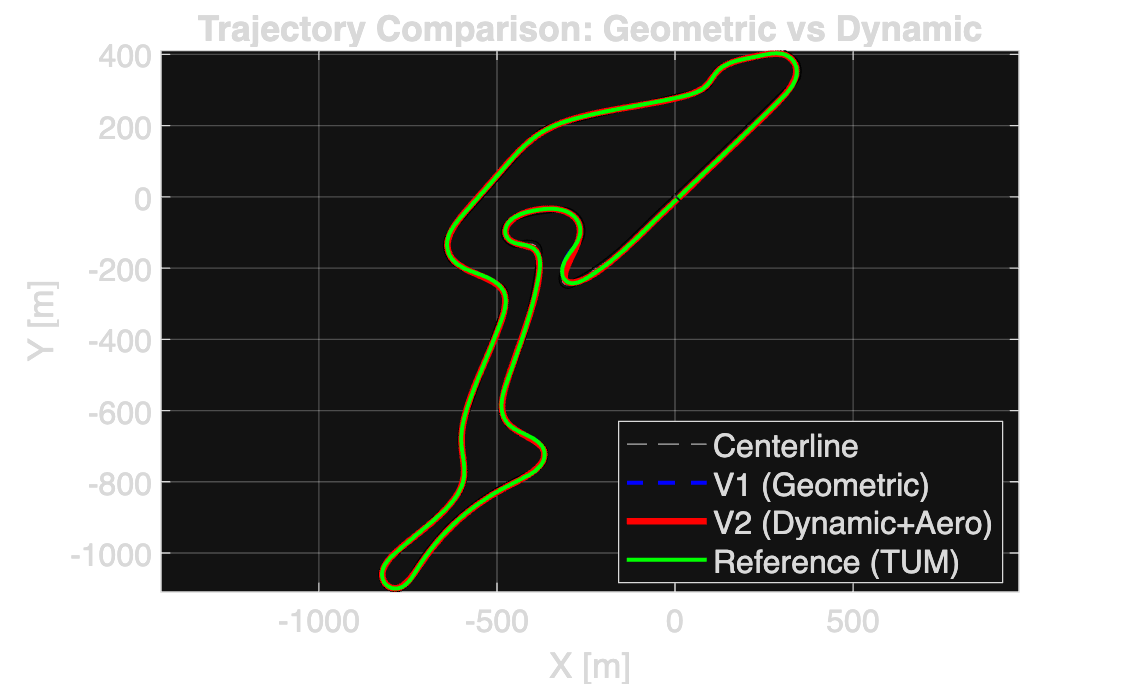

param.Cl_A = 3.8;       % Downforce Area
param.m    = 750;       % Mass [kg]
param.g    = 9.81;

% Aero Coefficients

coeff_aero   = (param.mu * 0.5 * param.rho * param.Cl_A) / param.m;
limit_static = param.mu * param.g;

# 1.3 Pre-compute Track Headings & Boundaries

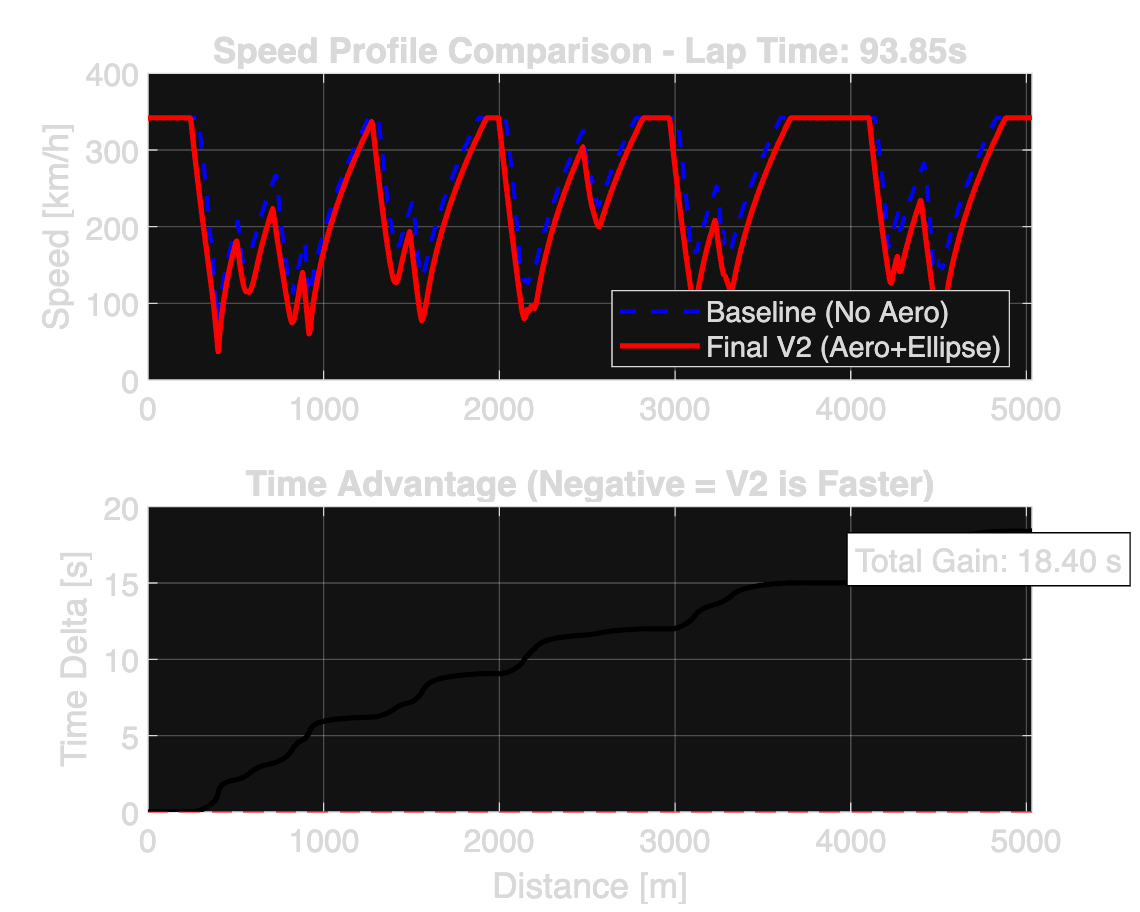

% Apply cubic smoothing spline to remove numerical noise
% p is the smoothing parameter: 0.999 is close to the original data but smooths jitters
p_smooth = 0.999; 
x_ref_smooth = csaps(1:N, x_center, p_smooth, 1:N)';
y_ref_smooth = csaps(1:N, y_center, p_smooth, 1:N)';

theta_track = zeros(N,1);
for k = 2:N-1
    theta_track(k) = atan2(y_ref_smooth(k+1)-y_ref_smooth(k-1), x_ref_smooth(k+1)-x_ref_smooth(k-1));
end
theta_track(1) = atan2(y_ref_smooth(2)-y_ref_smooth(N), x_ref_smooth(2)-x_ref_smooth(N));
theta_track(N) = atan2(y_ref_smooth(1)-y_ref_smooth(N-1), x_ref_smooth(1)-x_ref_smooth(N-1));
theta_track = unwrap(theta_track);


% Left and right boundaries (absolute coordinates)
x_L = x_center - w_left .* sin(theta_track);
y_L = y_center + w_left .* cos(theta_track);
x_R = x_center + w_right .* sin(theta_track);
y_R = y_center - w_right .* cos(theta_track);

% Reference data package for solver
ref.x = x_center; ref.y = y_center; ref.th = theta_track;
ref.xL = x_L; ref.yL = y_L; ref.xR = x_R; ref.yR = y_R;


## 2. PHASE V1: GEOMETRIC OPTIMIZATION (Standard)

fprintf('\n=== 2. PHASE V1: GEOMETRIC PATH (Constant Speed) ===\n');

% YALMIP Variables (Decision Variables)
x=sdpvar(N,1); 
y=sdpvar(N,1); 
theta=sdpvar(N,1); 
delta=sdpvar(N-1,1);
z=sdpvar(N,1);
dtheta=sdpvar(N,1);
slack_cycle = sdpvar(4,1);
% --- INITIALIZATION ---
assign(x, x_center); assign(y, y_center);
assign(theta, theta_track); assign(z, 0.5*ones(N,1));
assign(slack_cycle, zeros(4,1));

## --- Constraints V1 ---

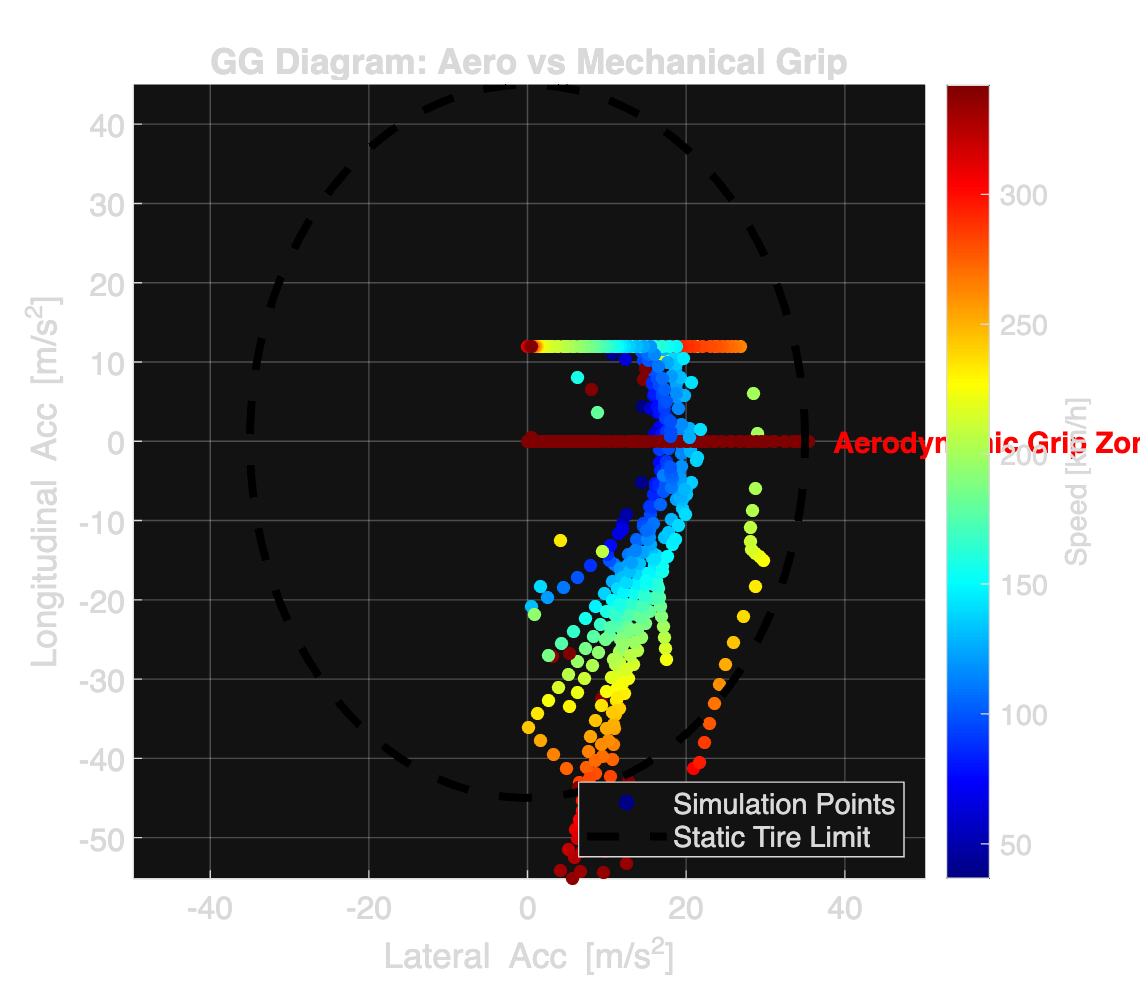

cons = [];
%--- ROBUST CYCLIC CONSTRAINTS ---
% Allow tiny slack instead of hard equality to prevent crashing
cons = [cons, x(1) - x(N) == slack_cycle(1)];
cons = [cons, y(1) - y(N) == slack_cycle(2)];
cons = [cons, z(1) - z(N) == slack_cycle(3)];
cons = [cons, delta(1) - delta(end) == slack_cycle(4)];; 
% RELATIVE Heading Constraint (Handles 2pi wrap correctly)
cons = [cons, (theta(1) - ref.th(1)) == (theta(N) - ref.th(N))];
% Boundaries & Dynamics
cons = [cons, x == x_L + z.*(x_R-x_L), y == y_L + z.*(y_R-y_L), 0 <= z <= 1];
cons = [cons, dtheta == theta - ref.th];

% Removed hard +/- 90 constraint to avoid feasibility issues
cons = [cons, delta_min <= delta <= delta_max];


Done. Analysis Complete.



% Geometric Kinematics
for k = 1:N-1
    d = sqrt((ref.x(k+1)-ref.x(k))^2 + (ref.y(k+1)-ref.y(k))^2);
    cons = [cons, ((x(k+1)-x(k))*(-sin(ref.th(k))) + (y(k+1)-y(k))*cos(ref.th(k))) == d * dtheta(k)];
    cons = [cons, theta(k+1) == theta(k) + (d/L)*delta(k)];
end
% --- Objective V1 (Minimize Curvature & Length) ---
dx_seg=sdpvar(N-1,1); 
dy_seg=sdpvar(N-1,1); 
kappa=sdpvar(N-1,1);
dDelta=sdpvar(N-2,1);

cons_obj = [];
for k = 1:N-1
    d = sqrt((ref.x(k+1)-ref.x(k))^2 + (ref.y(k+1)-ref.y(k))^2);
    cons_obj = [cons_obj, kappa(k) == (theta(k+1)-theta(k))/d];
end

% Weights (V1 Standard)
w_len = 10; w_smooth = 1000; w_curv = 1e5;

obj = w_len * sum(dx_seg.^2 + dy_seg.^2) + ... % Approx length
      w_smooth * (dDelta'*dDelta) + ...        % Smooth inputs
      w_curv * (kappa'*kappa);                 % Minimize curvature

ops = sdpsettings('solver','gurobi','verbose',0,'usex0', 1);
sol = optimize([cons, cons_obj], obj, ops);


% --- CHECK LINEARIZATION VALIDITY (Insert at end of Phase 2) ---
if sol.problem ~= 0
    % Calculate heading error relative to reference
    th_error = value(theta) - ref.th;
    
    % Wrap error to [-pi, pi] to handle the loop reset correctly
    th_error = atan2(sin(th_error), cos(th_error));
    
    max_err_deg = max(abs(rad2deg(th_error)));
    fprintf('   -> Max Heading Deviation: %.2f deg\n', max_err_deg);
    
    if max_err_deg > 30
        warning('LINEARIZATION ISSUE: Deviation > 30 deg. The model assumption sin(x)=x is failing.');
        fprintf('      Fix: Increase w_len weight or smooth the reference centerline.\n');
    else
        fprintf('   -> Linearization Assumption: VALID (Model is accurate)\n');
    end
else
    warning('V1 Optimization failed! Check constraints.');
end

% Store V1 Results (Keep this line)
path_v1.x = value(x); path_v1.y = value(y); path_v1.th = value(theta);
% NaN Check before Phase 3
if any(isnan(path_v1.x))
    error('Optimization returned NaNs. Check track data for duplicates.');
end

## 3. PHYSICS COMPARISON (Baseline vs Aero+Ellipse)

fprintf('\n=== 3. PHYSICS ENGINE COMPARISON (On V1 Path) ===\n');

% 3.1 Recalculate Geometry of V1 Path (With Smoothing)
x_raw = value(path_v1.x);
y_raw = value(path_v1.y);

p_smooth = 0.999; 
x_smooth = csaps(1:N, x_raw, p_smooth, 1:N)';
y_smooth = csaps(1:N, y_raw, p_smooth, 1:N)';

% Recalculate derivatives on smoothed path
dx = diff(x_smooth); 
dy = diff(y_smooth);
ds = sqrt(dx.^2 + dy.^2); 
ds = [ds; ds(end)]; % Pad end

% Recompute heading (continuous)
th_new = atan2(dy, dx);
th_new = unwrap([th_new; th_new(end)]); 
% Smooth Curvature Calculation
dth = diff(th_new);
dth(dth>pi) = dth(dth>pi)-2*pi; 
dth(dth<-pi) = dth(dth<-pi)+2*pi;
dth = [dth; dth(end)];

% Add epsilon to ds to avoid division by zero
k_geo = abs(dth) ./ (ds + 1e-3); 

% Limit erratic curvature spikes (optional safety)
k_geo(k_geo > 0.5) = 0.5;
% --- A. BASELINE (Decoupled) ---
E_base = sdpvar(N,1);
cons_b = [0 <= E_base <= param.v_max^2, E_base(1)==E_base(end)];
for k=1:N-1
    cons_b = [cons_b, E_base(k)*k_geo(k) <= param.a_lat_max]; % Cornering
    acc = (E_base(k+1)-E_base(k))/(2*ds(k));
    cons_b = [cons_b, -param.a_brk_max <= acc <= param.a_acc_max]; % Longitudinal
end
optimize(cons_b, -sum(E_base), ops);
v_base = sqrt(value(E_base));
t_base = sum(ds(1:end-1)./(0.5*(v_base(1:end-1)+v_base(2:end))+1e-3));

% --- PHYSICS MODEL: AERO + FRICTION ELLIPSE (SOCP) ---
fprintf('   -> Solving with Aero-Enhanced Friction Ellipse...\n');

% 1. Variables
E_opt = sdpvar(N,1);
cons_p = [0 <= E_opt <= param.v_max^2, E_opt(1)==E_opt(end)];

for k = 1:N-1
    % --- A. Forces Demand ---
    % Lateral Acceleration Demand (Centrifugal)
    % a_lat = v^2 * curvature
    lat_acc = E_opt(k) * k_geo(k);
    
    % Longitudinal Acceleration Demand (Engine/Brakes)
    % a_lon = d(v^2)/2ds
    lon_acc = (E_opt(k+1) - E_opt(k)) / (2*ds(k));

    % --- C. The Constraint (SOCP) ---
    % We constrain the MECHANICAL force from tires.
    % Tire_Force <= Available_Grip
    % norm([Lat, Lon]) <= Static_Grip + Aero_Grip
    
    % Note: Gravity (g_lon) is an external force. 
    % The tires only need to provide (lon_acc - g_lon).
    
    cons_p = [cons_p, norm([lat_acc; (lon_acc)], 2) <= limit_static + coeff_aero * E_opt(k)];
    
    % Engine Power Limit (Engine cannot use aero to get stronger, only tires do)
    cons_p = [cons_p, lon_acc <= param.a_acc_max];
end

% 3. Solve
optimize(cons_p, -sum(E_opt), ops);

% 4. Save Results
v_ell = sqrt(value(E_opt));
t_ell = sum(ds(1:end-1) ./ (0.5*(v_ell(1:end-1)+v_ell(2:end)) + 1e-3));

fprintf('   -> Final Lap Time (Aero+Ellipse): %.3f s\n', t_ell);

## 4. PHASE V2: ITERATIVE OPTIMIZATION (Dynamic Path)

fprintf('\n=== 4. PHASE V2: ITERATIVE OPTIMIZATION ===\n');

max_iter = 3; 
v_profile = v_ell; % Start with the V1 Ellipe speed
hist_time = [];

for iter = 1:max_iter
    fprintf('   -> Iteration %d/%d... ', iter, max_iter);
    
    % --- 4.1 Path Optimization (Weighted) ---

    % Redefine variables to avoid conflicts
    x=sdpvar(N,1); y=sdpvar(N,1); theta=sdpvar(N,1); delta=sdpvar(N-1,1);
    z=sdpvar(N,1); dtheta=sdpvar(N,1); kappa=sdpvar(N-1,1);
    slack_cycle = sdpvar(4,1);
    
    % Constraints (Same as V1 + Rate of Change)
    cons = [];
    %Cyclic constraints
% ROBUST CYCLIC CONSTRAINTS (Same as Phase 1)
    cons = [cons, x(1)-x(N)==slack_cycle(1), y(1)-y(N)==slack_cycle(2), ...
                  z(1)-z(N)==slack_cycle(3), delta(1)-delta(end)==slack_cycle(4)];
    cons = [cons, (theta(1) - ref.th(1)) == (theta(N) - ref.th(N))];
    cons = [cons, x == x_L + z.*(x_R-x_L), y == y_L + z.*(y_R-y_L), 0<=z<=1];
    cons = [cons, dtheta == theta - ref.th];
    cons = [cons, delta_min <= delta <= delta_max];
    
    % Rate of Change (Smoothness)
    d_delta_max = deg2rad(5);
    for k=1:N-2, cons=[cons, -d_delta_max <= delta(k+1)-delta(k) <= d_delta_max]; end
    
    for k = 1:N-1
        d = sqrt((ref.x(k+1)-ref.x(k))^2 + (ref.y(k+1)-ref.y(k))^2);
        cons = [cons, ((x(k+1)-x(k))*(-sin(ref.th(k))) + (y(k+1)-y(k))*cos(ref.th(k))) == d * dtheta(k)];
        cons = [cons, theta(k+1) == theta(k) + (d/L)*delta(k)];
        cons = [cons, kappa(k) == (theta(k+1)-theta(k))/d];
    end
    
% Adaptive Weights (Penalize curvature more where speed is high)
    w_vec = 2e5 * (v_profile(1:N-1)/param.v_max).^1.5 + 5000; % Higher speed = Higher penalty
    obj = 0.1*sum((diff(x)).^2 + (diff(y)).^2) + ...
      100*sum(diff(delta).^2) + ... 
      sum(w_vec .* (kappa.^2))+ ...
      1e9*(slack_cycle'*slack_cycle);          % Adaptive Curvature
          
    optimize(cons, obj, ops);
    
    % Store Path
    path_v2.x = value(x); path_v2.y = value(y); path_v2.th = value(theta);
    

## 4.2 Speed Optimization (Aero + ellipse) on New Path

    dx=diff(path_v2.x); dy=diff(path_v2.y);
    ds=sqrt(dx.^2+dy.^2); ds=[ds; ds(end)];
    % Recalculate curvature on new path
    dth=diff(path_v2.th);
    dth(dth>pi)=dth(dth>pi)-2*pi; dth(dth<-pi)=dth(dth<-pi)+2*pi;
    k_opt = abs([dth; 0])./(ds+1e-6);
    
    E=sdpvar(N,1);
    cons_v=[0<=E<=param.v_max^2, E(1)==E(end)];

   for k=1:N-1
        % 1. Calculate Acceleration Demands
        lat_acc = E(k) * k_opt(k);            % Lateral (Centrifugal)
        lon_acc = (E(k+1)-E(k))/(2*ds(k));    % Longitudinal (Brake/Throttle)
        
        
        
        % 3. Apply Aero + Ellipse Constraint (SOCP)
        % This forces Phase 4 to respect the advanced physics model
        cons_v = [cons_v, norm([lat_acc; (lon_acc)], 2) <= limit_static + coeff_aero * E(k)];
        
        % 4. Engine Power Limit
        cons_v = [cons_v, lon_acc <= param.a_acc_max];
    end
    optimize(cons_v, -sum(E), ops);
    
    v_profile = sqrt(value(E));
    
    % Calc Time
    t_iter = sum(ds(1:end-1)./(0.5*(v_profile(1:end-1)+v_profile(2:end))+1e-3));
    hist_time = [hist_time; t_iter];
    fprintf('Lap Time: %.3f s\n', t_iter);
end

t_final = hist_time(end);
v_final = v_profile;

## 5. VISUALIZATION & ANALYSIS

%% 5. VISUALIZATION & ANALYSIS
fprintf('\n=== 5. GENERATING PLOTS ===\n');

% Standardize Font Size for Presentation (Projector friendly)
pres_font = 12;

% --- PRE-CALCULATIONS FOR PLOTS ---
% 1. Time Delta Calculation (Where do we gain time?)
% Calculate cumulative time for both trajectories
dt_base = ds(1:end-1) ./ (0.5*(v_base(1:end-1) + v_base(2:end)) + 1e-3);
dt_final = ds(1:end-1) ./ (0.5*(v_final(1:end-1) + v_final(2:end)) + 1e-3);
time_cum_base = [0; cumsum(dt_base)];
time_cum_final = [0; cumsum(dt_final)];
time_delta = time_cum_final - time_cum_base; % Negative means V2 is faster

% 2. GG Diagram Data
a_lat_final = v_final(1:end-1).^2 .* k_opt(1:end-1);
a_lon_final = diff(v_final.^2) ./ (2*ds(1:end-1));

% --- FIGURE 1: TRAJECTORY MAP ---
figure('Name','Trajectories','Color','w', 'Position', [100 100 1000 600]);
plot(x_L, y_L, 'k', 'LineWidth', 0.5, 'HandleVisibility','off'); hold on;
plot(x_R, y_R, 'k', 'LineWidth', 0.5, 'HandleVisibility','off');
plot(x_center, y_center, 'Color', [0.7 0.7 0.7], 'LineStyle', '--', 'DisplayName', 'Centerline');

% Plot V1 and V2 with high contrast colors
plot(path_v1.x, path_v1.y, 'b--', 'LineWidth', 1.5, 'DisplayName', 'V1 (Geometric)');
plot(path_v2.x, path_v2.y, 'r-', 'LineWidth', 2.5, 'DisplayName', 'V2 (Dynamic+Aero)');

% Robust TUM Loading
raceline_file = '/Users/louisrodembourg/Desktop/Cours_Parme/Path_and_trajectory/Project_Car_trajectory/Circuits_Data/Nuerburgring_raceline.csv';
if isfile(raceline_file)
    fprintf('   -> Overlaying TUM raceline...\n');
    try
        opts2 = detectImportOptions(raceline_file);
        opts2.Delimiter = ','; opts2.VariableNamingRule = 'preserve';
        data_race = readtable(raceline_file, opts2);
        x_race_raw = data_race.("# x_m"); y_race_raw = data_race.y_m;
        plot(x_race_raw, y_race_raw, 'g-', 'LineWidth', 1.5, 'DisplayName', 'Reference (TUM)');
    catch
        warning('Could not parse TUM raceline file.');
    end
end

legend('Location', 'best', 'FontSize', pres_font);
title('Trajectory Comparison: Geometric vs Dynamic', 'FontSize', 14);
axis equal; grid on; set(gca, 'FontSize', pres_font);
xlabel('X [m]'); ylabel('Y [m]');

% --- FIGURE 2: TELEMETRY ANALYSIS (Speed & Time Delta) ---
figure('Name','Telemetry Analysis','Color','w', 'Position', [150 150 1000 800]);

% Subplot 1: Speed Profile
subplot(2,1,1);
d_cum = [0; cumsum(ds(1:end-1))];
plot(d_cum, v_base*3.6, 'b--', 'LineWidth', 1.5, 'DisplayName', 'Baseline (No Aero)'); hold on;
plot(d_cum, v_final*3.6, 'r-', 'LineWidth', 2.0, 'DisplayName', 'Final V2 (Aero+Ellipse)');
ylabel('Speed [km/h]', 'FontSize', pres_font); 
title(['Speed Profile Comparison - Lap Time: ' num2str(t_final, '%.2f') 's'], 'FontSize', 14);
legend('Location', 'best'); grid on; xlim([0 d_cum(end)]);
set(gca, 'FontSize', pres_font);

% Subplot 2: Time Delta (The most useful plot for analysis)
subplot(2,1,2);
plot(d_cum, time_delta, 'k-', 'LineWidth', 2);
yline(0, 'r--'); % Zero line
ylabel('Time Delta [s]', 'FontSize', pres_font); 
xlabel('Distance [m]', 'FontSize', pres_font);
title('Time Advantage (Negative = V2 is Faster)', 'FontSize', 14);
grid on; xlim([0 d_cum(end)]);
% Add annotation for total gain
total_gain = time_delta(end);
text(d_cum(end)*0.8, total_gain*0.9, sprintf('Total Gain: %.2f s', abs(total_gain)), ...
    'FontSize', 12, 'BackgroundColor', 'w', 'EdgeColor', 'k');
set(gca, 'FontSize', pres_font);


% --- FIGURE 3: ADVANCED GG DIAGRAM (Aero Visualization) ---
figure('Name','Aero GG Diagram','Color','w', 'Position', [200 200 800 700]);


% 1. Plot the Scatter points colored by speed
scatter(a_lat_final, a_lon_final, 25, v_final(1:end-1)*3.6, 'filled');
c = colorbar; c.Label.String = 'Speed [km/h]';
colormap jet; hold on;

% 2. Draw the STATIC Friction Ellipse (Mechanical Grip Limit)
% Equation: (lat/lat_max)^2 + (lon/brk_max)^2 = 1
th_ell = linspace(0, 2*pi, 100);
x_ell = param.a_lat_max * cos(th_ell);
y_ell = param.a_brk_max * sin(th_ell); % This assumes brk max for ellipse shape visualization
% Note: Real ellipse might differ for accel vs brake, but this is a good visual baseline
plot(x_ell, y_ell, 'k--', 'LineWidth', 3, 'DisplayName', 'Mechanical Grip Limit');

% 3. Formatting
xlabel('Lateral Acc [m/s^2]', 'FontSize', pres_font); 
ylabel('Longitudinal Acc [m/s^2]', 'FontSize', pres_font);
title('GG Diagram: Aero vs Mechanical Grip', 'FontSize', 14);
axis equal; grid on; set(gca, 'FontSize', pres_font);

% 4. Add "Aero Zone" Annotation
% Points outside the dashed line are purely due to Downforce
text(param.a_lat_max*1.1, 0, 'Aerodynamic Grip Zone', 'Color', 'r', 'FontSize', 11, 'FontWeight', 'bold');
legend('Simulation Points', 'Static Tire Limit', 'Location', 'SouthEast');

fprintf('\nDone. Analysis Complete.\n');